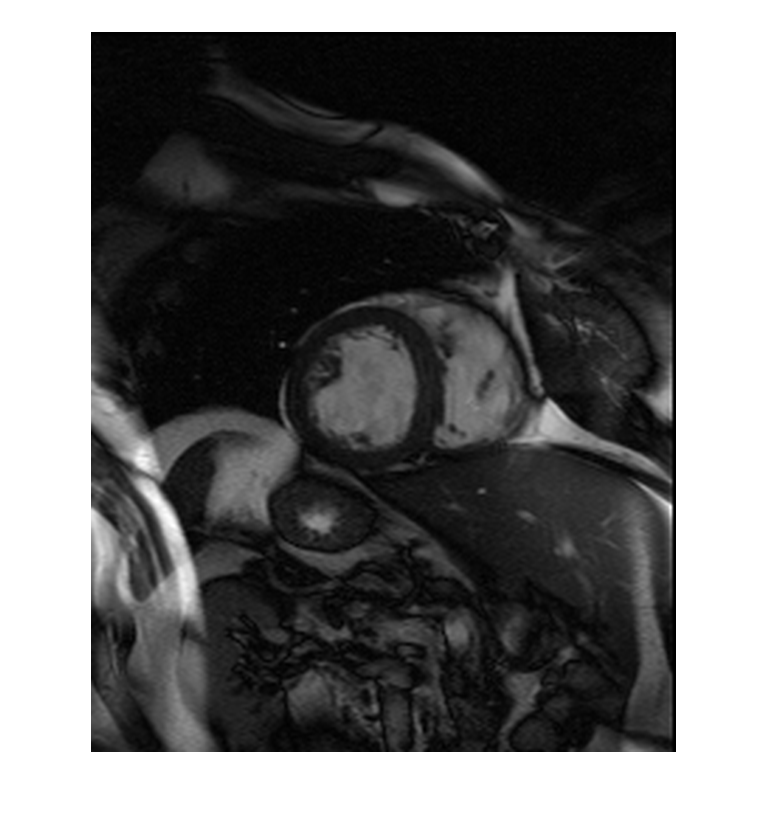

scanNumber = 1;
scan = imread(sprintf('MRIheart/MRI1_%02d.png', scanNumber));
figure(); imshow(scan);

segmenter = HeartSegmenter(scan);

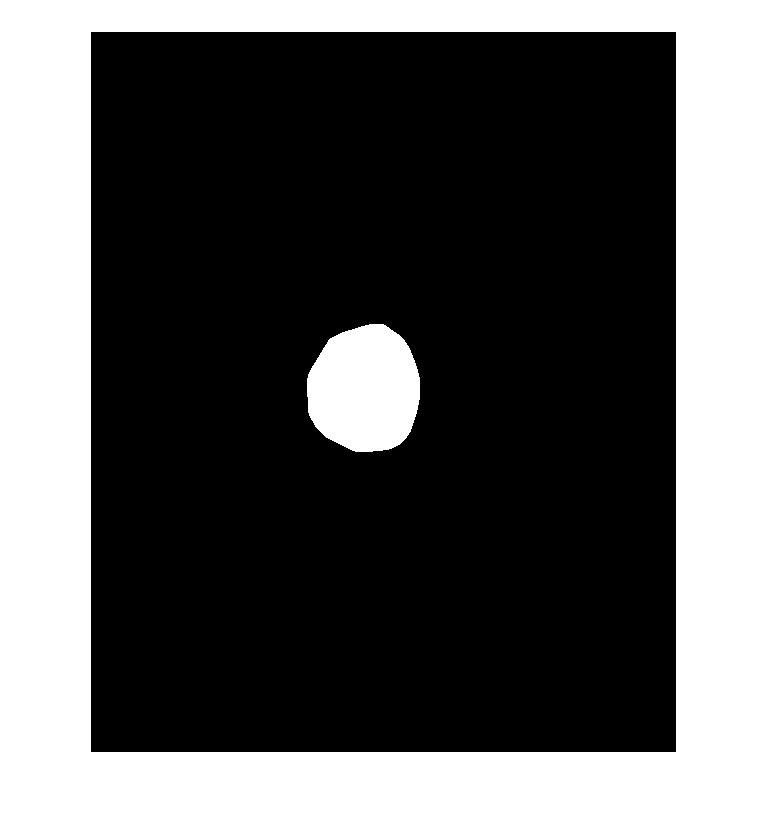

mask = segmenter.getHeartMask();
imshow(mask);

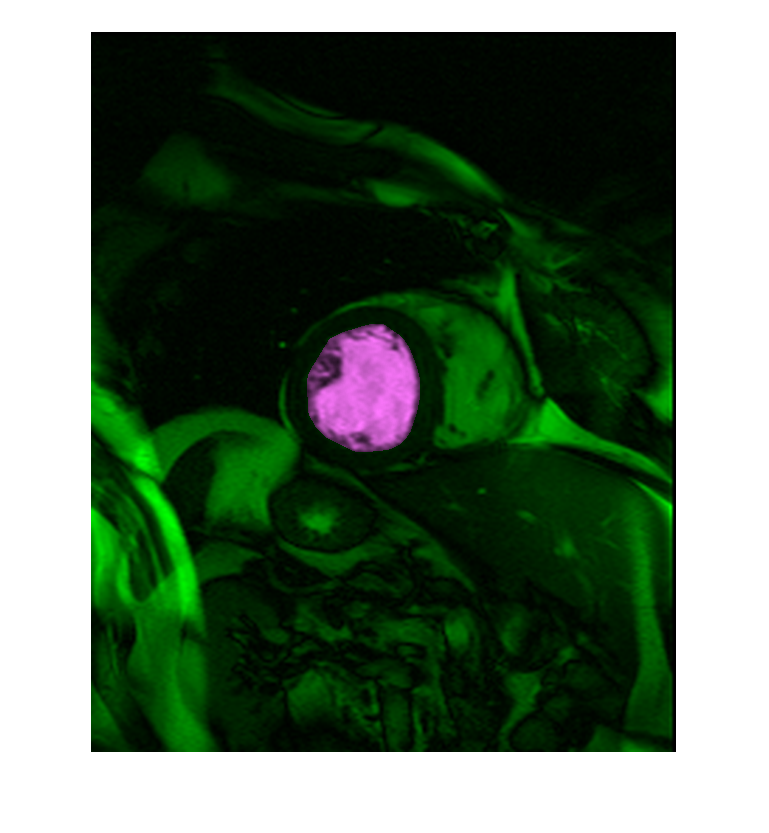

imshowpair(scan, uint8(mask) .* scan);

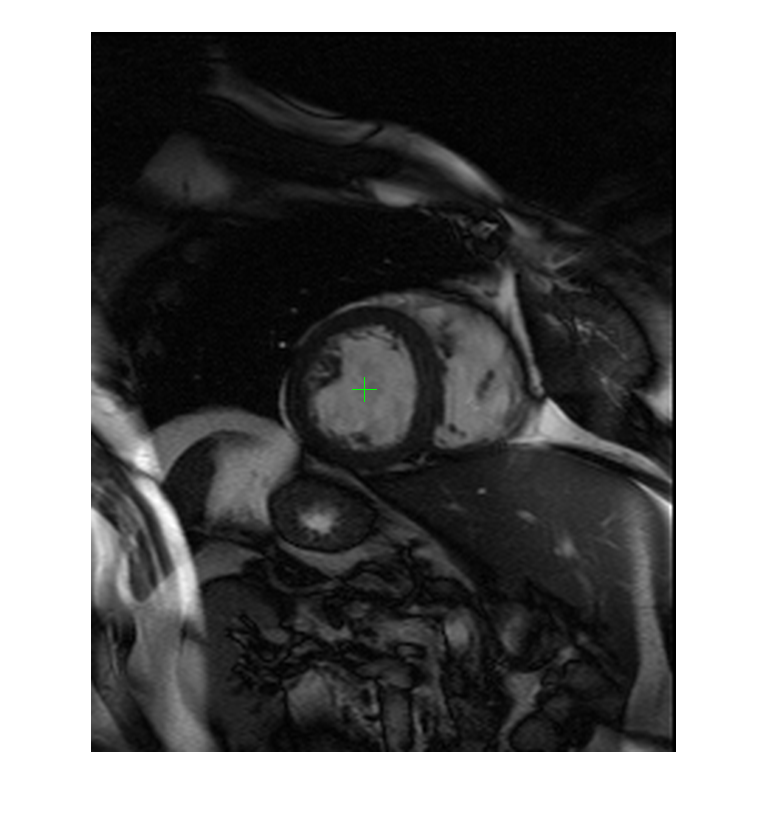

[centroid, diameter] = segmenter.getCentroid(mask);
centreMarked = insertMarker(scan, centroid, 'Size', 12);
imshow(centreMarked);

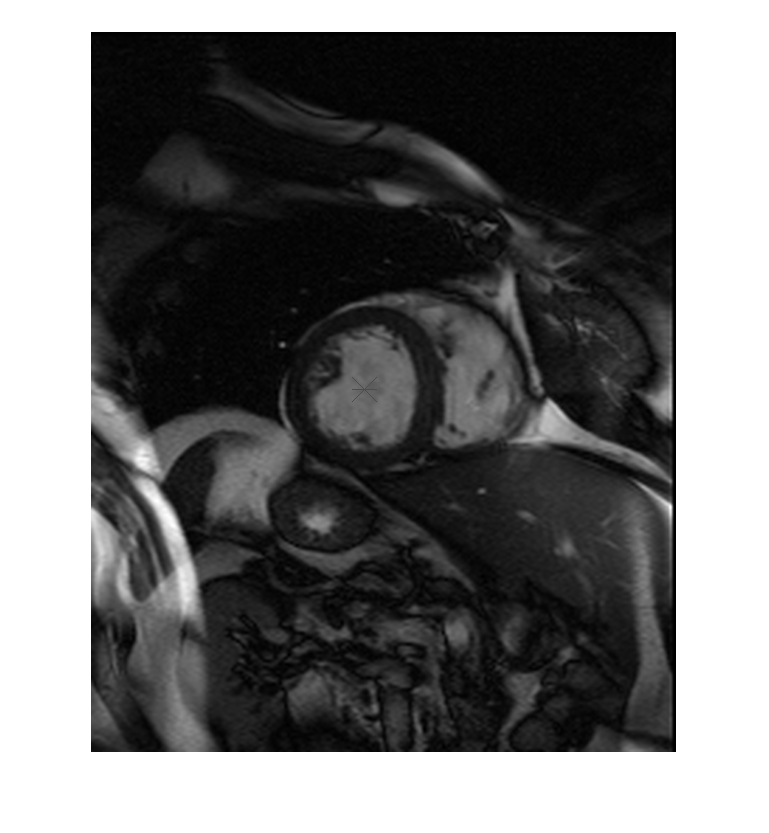

figure();
centreMarked = insertMarker(scan, centroid, '*', 'Size', 12, 'Color', 'red');
imshow(centreMarked);

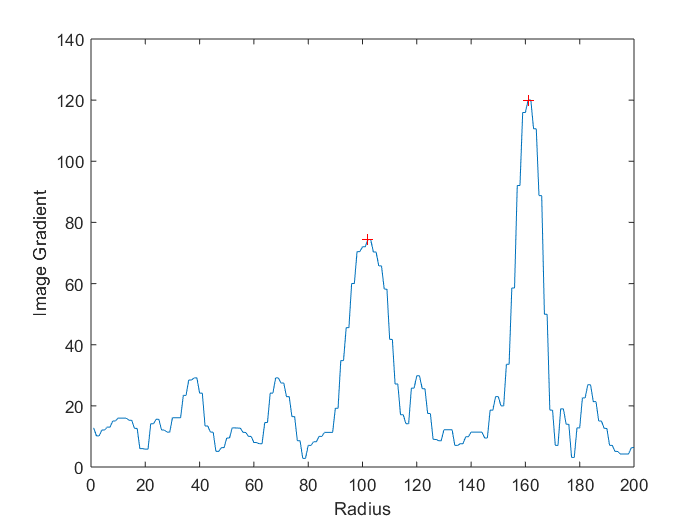

[radii, thetas, xs, ys] = segmenter.getPolarCoordinates(centroid);

startingPoints = segmenter.getStartingRadii(xs, ys);

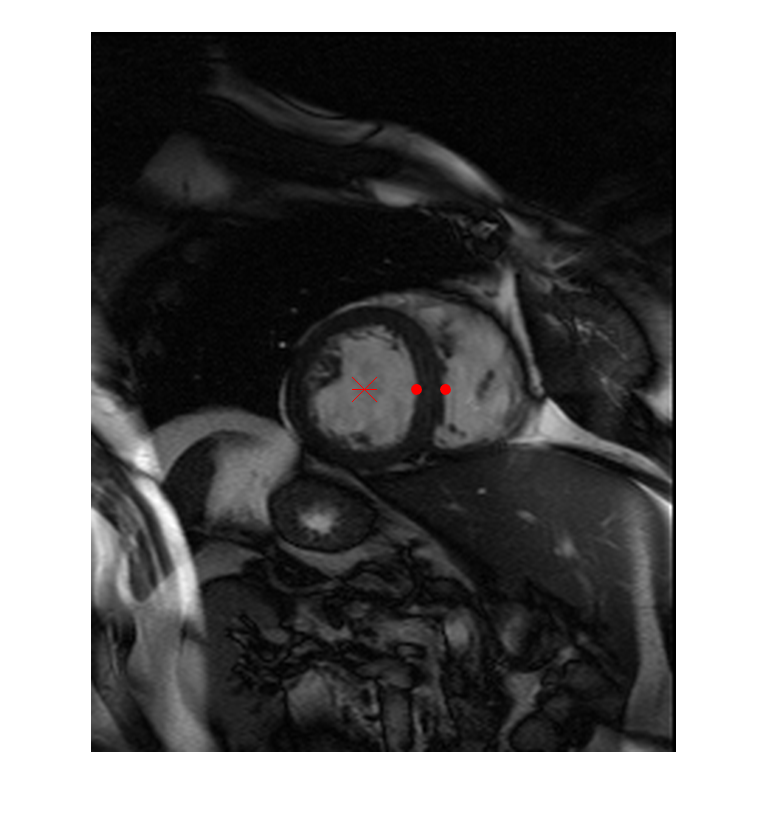

figure();
imshow(centreMarked); hold on;
scatter(startingPoints, [centroid(2) centroid(2)], 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r'); hold off; 

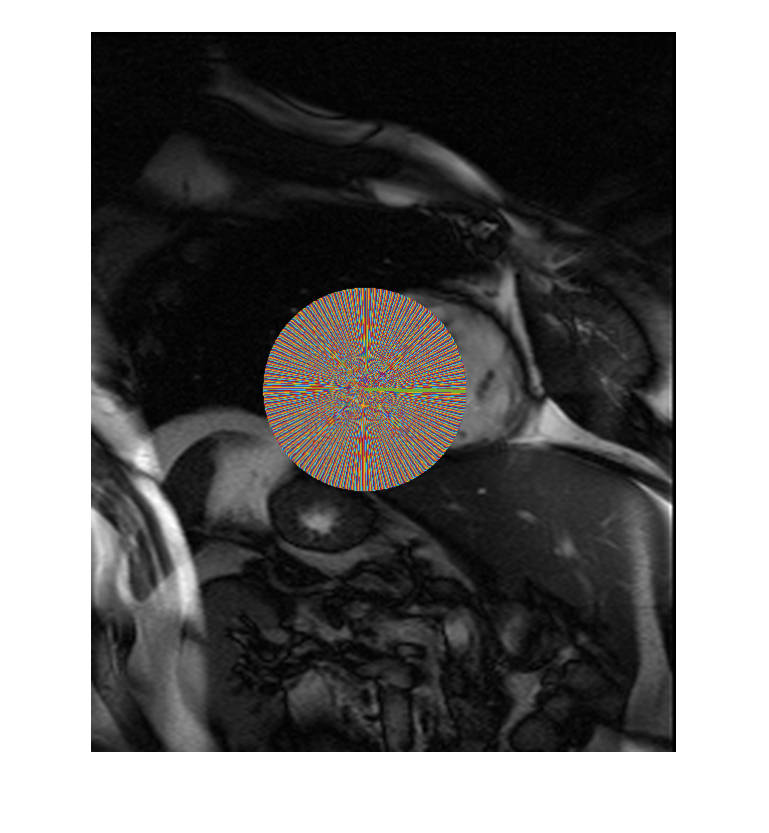

figure(); imshow(scan); hold on;
colours = hsv(length(thetas));

for t = 1:length(thetas)
    scatter(xs(:,t), ys(:,t), '.', 'MarkerFaceColor', colours(t,:));
end
hold off;

[insidePath, outsidepath] = segmenter.getOutlines();

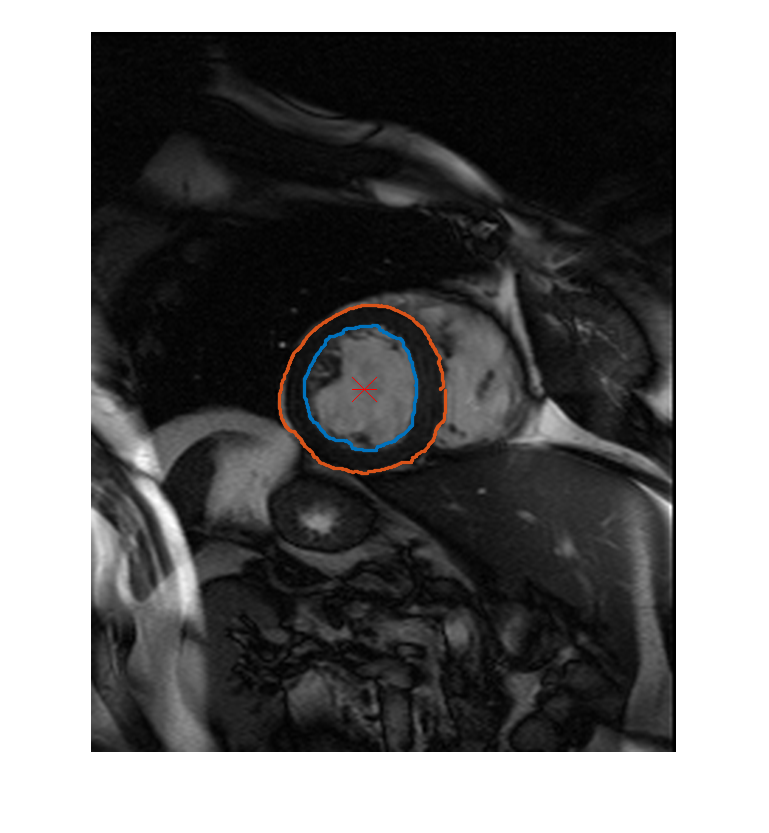

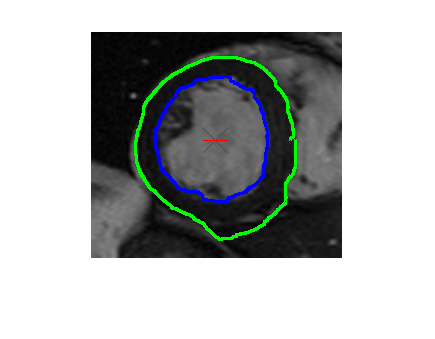


figure(); 
imshow(centreMarked); hold on;
scatter(insidePath(:,1), insidePath(:,2), '.');
scatter(outsidepath(:,1), outsidepath(:,2), '.');